### 使用全局变量的技术编写一个GUI程序

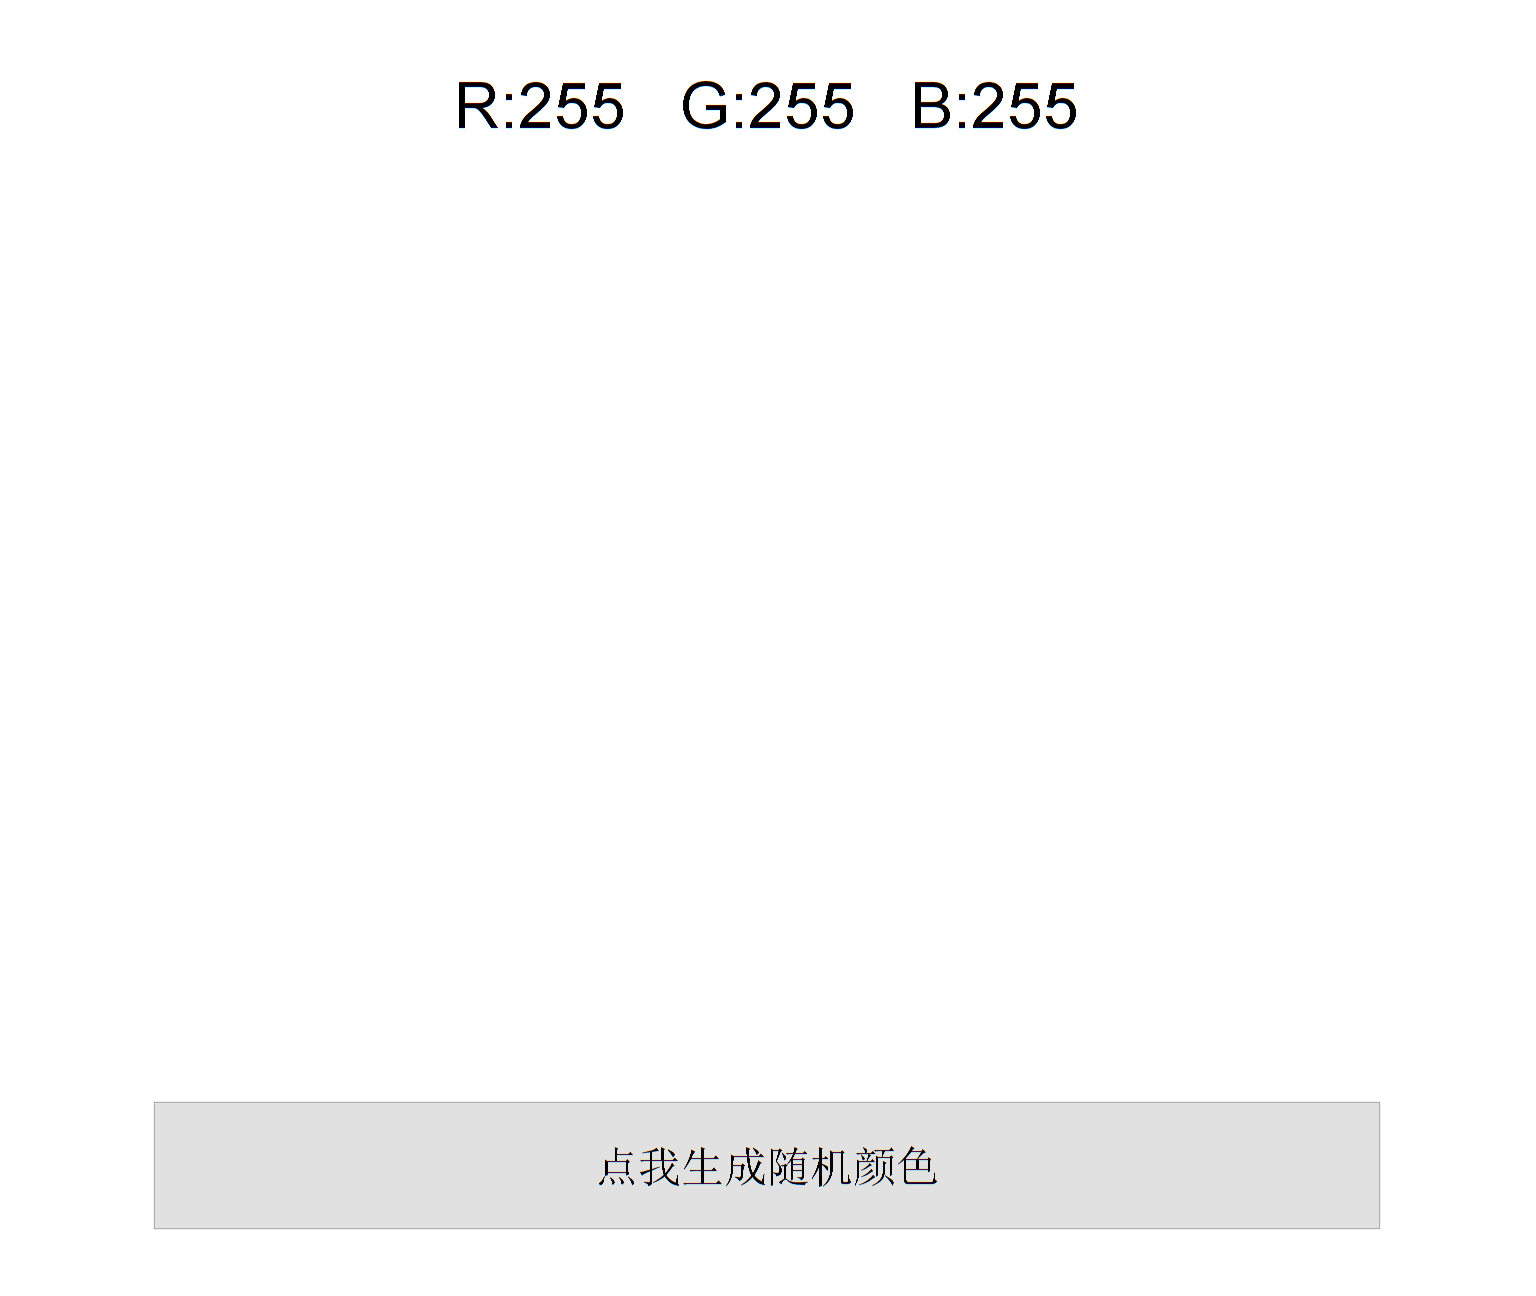

GUI_color

（我更推荐大家学习APPdesigner，这个才是MATLAB发展的趋势，GUI未来可能会被MATLAB淘汰）

APPdesigner是面向对象编程，建议先了解下MATLAB中如何创建和实例化一个类，里面会学到新的关键字classdef

function GUI_color()
    global GUI  % 将GUI设置为全局变量
    GUI.f = figure;  % GUI是一个结构体数组
    GUI.f.Units = 'normalized';
    GUI.f.Position = [0.3 0.2 0.4 0.6];  % 指定为[left bottom width height] 形式的向量
    GUI.f.MenuBar = 'none'; % 去掉菜单栏
    GUI.f.Color = [1 1 1];  % 背景颜色为白色
    GUI.f.NumberTitle = 'off';  % 关闭带编号的标题
    GUI.f.Name = '第一个GUI应用';
    GUI.ax = axes(GUI.f,'Position',[0.17 0.2 0.66 0.66]);
    % 生成一个按钮
    uicontrol(GUI.f, 'Style','pushbutton','String','点我生成随机颜色', ...
        'FontSize',16,'Units','normalized','Position',[0.1 0.05 0.8 0.1], ...名称-值参数Position和Units的位置不能交换
        'Callback', @change_color);  % 回调函数：随机生成颜色
    % 生成一个文本段用于显示当前RGB
    GUI.t = uicontrol(GUI.f, 'Style','text','String','R:255   G:255   B:255', ...
        'FontSize',24,'Units','normalized','Position',[0.1 0.85 0.8 0.1], ...
        'BackgroundColor',[1 1 1]);
    GUI.im = ones(1,1,3);  % 初始颜色，全白色的图片
    imshow(GUI.im,'Parent',GUI.ax)
end
function change_color(~,~)
    global GUI
    GUI.im = rand(1,1,3);
    imshow(GUI.im,'Parent',GUI.ax)
    change_text
end
function change_text
    global GUI
    q = round(GUI.im*255);
    c = sprintf('R:%03d   G:%03d   B:%03d',q(1),q(2),q(3));
    GUI.t.String = c;
end


配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1Xm41167aC/](https://www.bilibili.com/video/BV1Xm41167aC/)